f = 1/32

f = 0.0313

x = (.5 + (1/2)*exp(-1j * 2 * pi*f)) ^ 84

x = -0.2551 - 0.6159i


abs(x)

ans = 0.6667

angle(x)

ans = -1.9635




% An FIR system is of the form

% y[n]=x[n]–x[n−1]
% and has input x[n]=ej(2πn/14) The associated output is of the form
% y[n]=Aej(2πf^n+ϕ)

freq = 1/14

freq = 0.0714

x = 1 - exp(1j*2*pi*freq)

x = 0.0990 - 0.4339i

abs(x)

ans = 0.4450

angle(x)

ans = -1.3464

freq = 0.0714

phase = 1.5708

freq = 1/14

x = 0.3765 + 1.2182i

phase = pi/2

ans = 1.2750

% maybe just double freq and add pi/2 to the previous phase

ans = 1.2710


x = 2*exp(1j*phase) - 2*exp(1j*(2*pi*freq + phase))*sin(2*pi/14)
abs(x)
angle(x)


% A signal x[n] has one period given by
% x[n]={−2, n = 0, 1
%        0, n= 2,3,…,17

k = 15

% Let x[n] have DFT coefficients X[k]

X = -3.0000 - 1.7321i


k = 15

ans = -3

X = -2 + (-2*exp(-1j*2*pi*(k/18)))

ans = -1.7321


real(X)
imag(X)


% X[k]=A(1+e−jk2π/N)

k = 1

N = 18

k = 1

x = -3.6454 + 1.3268i

N = 18
x = -1*( (1+exp(-1j * 2*pi * (k/N))) * (1+exp(-1j * 2*pi * (k/N))))

ans = 3.8794

ans = 2.7925

abs(x)

phi3 = 0

A = 1.2393

phi = -1.9861

angle(x)


% after fourier series by integration


k = -5

k = -5

X = 0.0000 + 0.2546i

X = ((1/(-1j*pi*k))*(exp(-1j*pi*k) - 1)) + ((-1/(-1j*pi*k))*(exp(-1j*2*pi*k) - exp(-1j*pi*k)))

ans = 0.2546

imag(X)


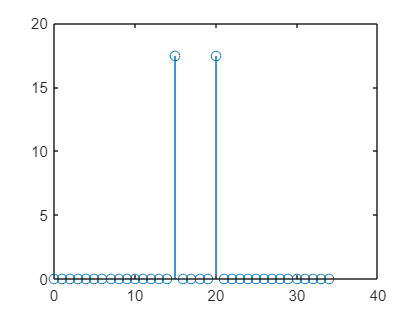

% Match the DFT magnitude shown in the figures with the 
% time signals.  In all cases the DFT length is 35

nn = [0:34];

xn15 = cos(2*pi*15*nn/35);
figure
stem([0:34], abs(fft(xn15)));

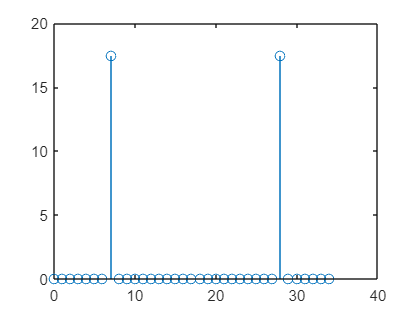


xn8 = cos(2*pi*8*nn/40);
figure
stem([0:34], abs(fft(xn8)));

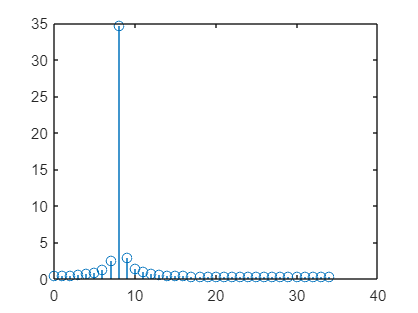


xn9 = exp(1j*2*pi*9*nn/39);
figure
stem([0:34], abs(fft(xn9)));

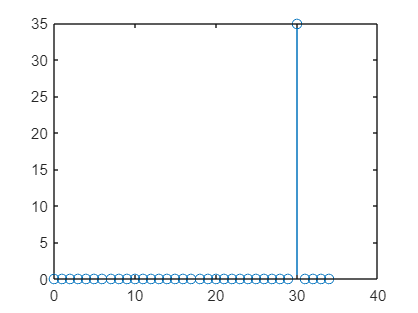


xn30_35 = exp(1j*2*pi*30*nn/35);
figure
stem([0:34], abs(fft(xn30_35)));

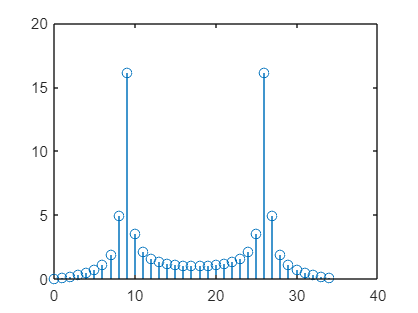


xn30_40 = cos(2*pi*30*nn/40);
figure
stem([0:34], abs(fft(xn30_40)));

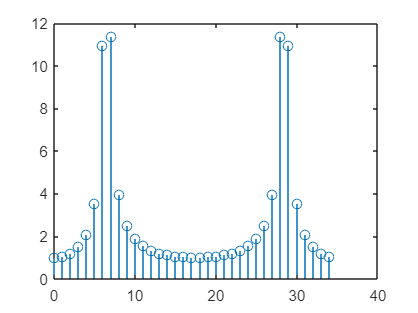


xn6_5 = cos(2*pi*6.5*nn/35);
figure
stem([0:34], abs(fft(xn6_5)));

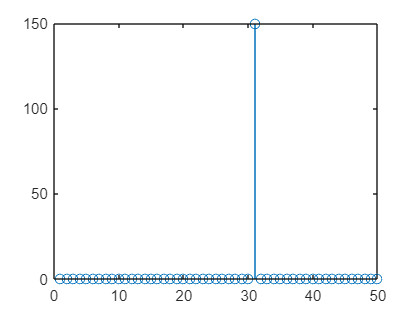

clear

t=0:0.01:0.99;
tone.amp = [4 3 2];
tone.frq = [21 30 5]*2*pi;
tone.phs = [pi/4 0 pi/2];
 

for  i = 1:3
 x(i,:) = tone.amp(i)*cos(tone.frq(i)*t + tone.phs(i));
 y(i,:) = abs(fft(x(i,:)));
end
 

stem(y(2,1:50)) 

% x(t)=3cos(2πt+ϕ1) + 4cos(2πt+ϕ2) 
% Use the phasor addition rule to write x(t)=Acos(2πt+ϕ)

phi1 = pi/3;
phi2 = -pi/2;
phi3 = 0;

amps = [1,2,-1];
phases = [phi1,phi2,phi3];

phasor_add = sum(amps.*exp(1i * phases));
A = abs(phasor_add)

A = 1.2393

phi = angle(phasor_add)

phi = -1.9861


k = 20

k = 20


X = ((1/(1j*k*pi))*(1-exp(1j*pi*k))) - ((1/(1j*k*pi)*(exp(-1j*k*pi)-1)))

X = 0


real(X)

ans = 0

imag(X)

ans = 0